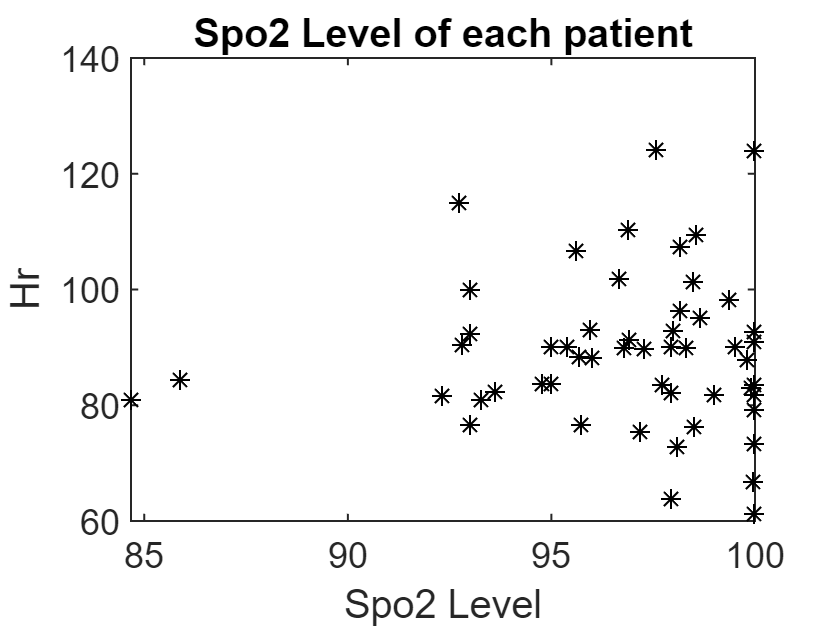

data;
pat = zeros(53,2);
numPat = numel(data);
for p = 1:numPat
    r=1;
    pat(p,r) = nanmean(data(p).ref.params.spo2.v);
    %pat(p).rr = nanmean(data(p).ref.params.rr.v);
    r = 2;
    pat(p,r) = nanmean(data(p).ref.params.hr.v);        
end

figure;
plot(pat(:,1),pat(:,2), 'k*','MarkerSize',5)
title('Spo2 Level of each patient');
ylabel 'Hr'
xlabel 'Spo2 Level'

[idx, C] = kmeans(pat,7);

Unrecognized function or variable 'best_kmeans'.


figure
gscatter(pat(:,1),pat(:,2),idx,'bgmrcky')
hold on
plot(C(:,1),C(:,2),'kx')
legend('Cluster 1','Cluster 2','Cluster 3', 'Cluster 4', 'Cluster 5', 'Cluster 6', ',Cluster 7', 'Cluster Centroid')

data;
pat = zeros(53,2);
numPat = numel(data);
for p = 1:numPat
    r=1;
    pat(p,r) = nanmean(data(p).ref.params.spo2.v);
    %pat(p).rr = nanmean(data(p).ref.params.rr.v);
    r = 2;
    pat(p,r) = nanmean(data(p).ref.params.rr.v);      
end

figure;
plot(pat(:,1),pat(:,2), 'k*','MarkerSize',5)
title('Spo2 Level of each patient');
ylabel 'Rr'
xlabel 'Spo2 Level'
[idx, C] = kmeans(pat,7);

figure
gscatter(pat(:,1),pat(:,2),idx,'bgmrcky')
hold on
plot(C(:,1),C(:,2),'kx')
legend('Cluster 1','Cluster 2','Cluster 3', 'Cluster 4', 'Cluster 5', 'Cluster 6', ',Cluster 7', 'Cluster Centroid')